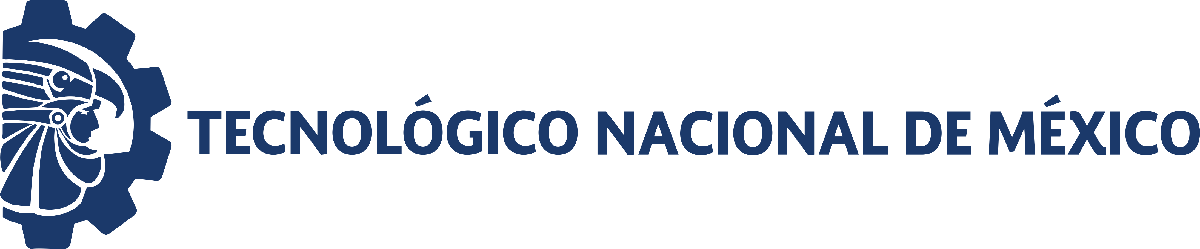                                 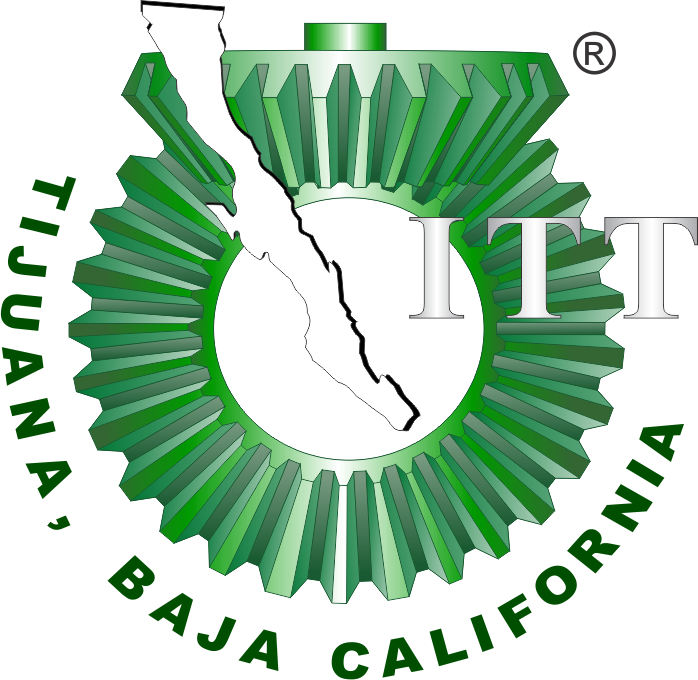

# Práctica cero: Mecánica pulmonar

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

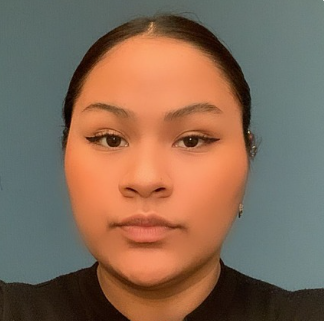

Nombre del alumno: Pamela Escobedo Sandoval

Número de control: 20211965

Correo institucional: 20211965**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning( 'off', 'all')
tend = '10' ;
file = 'sistema';
open_system(file);
parameter.StopTime = tend;
parameter.Solver = 'ode15s'

parameter = struct with fields:
    StopTime: '10'
      Solver: 'ode15s'


parameter.Maxstep = '1E-3' ;
%set_param('Sistema/Pao(t)','VectorFormat','1-D array');

## Respuesta al escalón

Signal ='Step';
set_param('sistema/S1', 'sw', '1');
set_param('sistema/Pao(t)', 'sw','1');
x1 = sim(file,parameter);

Found algebraic loop containing: 
sistema/PA1(t)/Gain2
sistema/PA1(t)/Gain
sistema/PA1(t)/Derivative
sistema/PA1(t)/Add (algebraic variable)


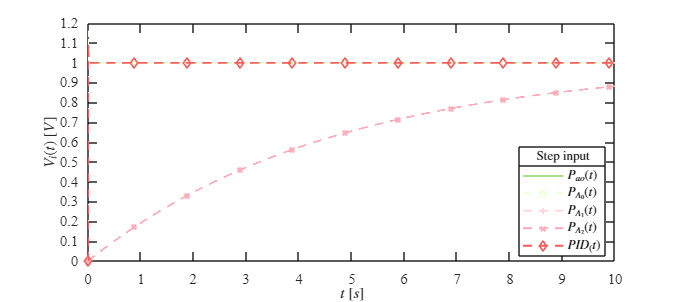

plotsignals(x1.t,x1.Pao,x1.P0,x1.P1,x1.P2,x1.PID,Signal)

## Respuesta al impulso

Signal = 'Impulso' ;
set_param( 'sistema/S1', 'sw', '0');
set_param( 'sistema/Pao(t)', 'sw','1');

x2 = sim (file,parameter);

Found algebraic loop containing: 
sistema/PA1(t)/Gain2
sistema/PA1(t)/Gain
sistema/PA1(t)/Derivative
sistema/PA1(t)/Add (algebraic variable)


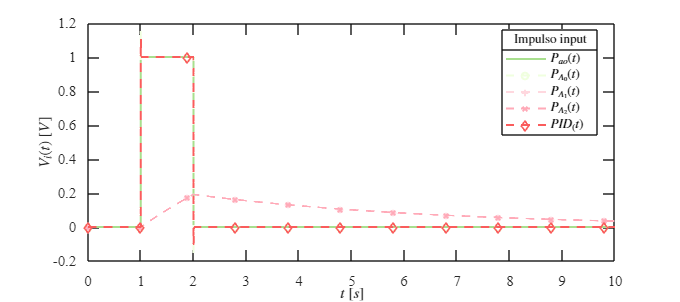

plotsignals(x2.t, x2.Pao, x2.P0, x2.P1, x2.P2, x2.PID, Signal)

## Respuesta a la rampa

Signal = 'Ramp' ;
set_param( 'sistema/S2', 'sw', '1');
set_param( 'sistema/Pao(t)', 'sw','0');
x3 = sim (file,parameter);

Found algebraic loop containing: 
sistema/PA1(t)/Gain2
sistema/PA1(t)/Gain
sistema/PA1(t)/Derivative
sistema/PA1(t)/Add (algebraic variable)


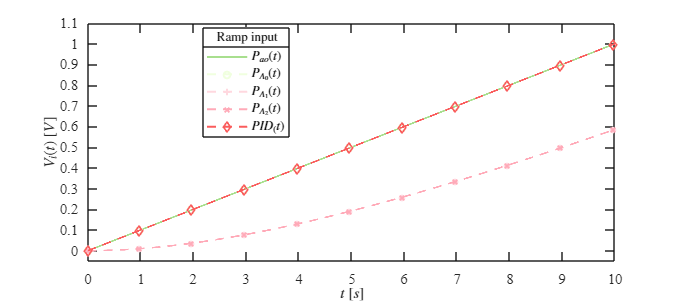

plotsignals(x3.t, x3.Pao, x3.P0, x3.P1, x3.P2, x3.PID, Signal)

## Respuesta a la función sinusoidal

Signal = 'sin' ;
set_param( 'sistema/S2', 'sw', '0');
set_param( 'sistema/Pao(t)', 'sw','0');
x4 = sim (file,parameter);

Found algebraic loop containing: 
sistema/PA1(t)/Gain2
sistema/PA1(t)/Gain
sistema/PA1(t)/Derivative
sistema/PA1(t)/Add (algebraic variable)


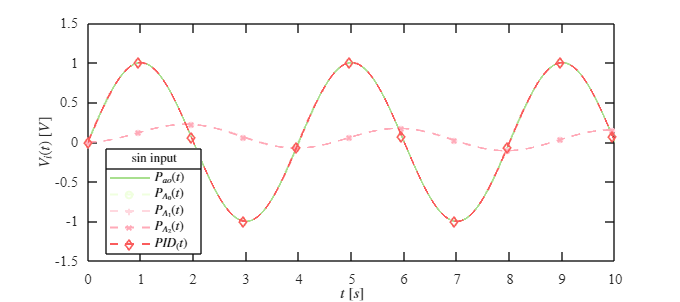

plotsignals(x4.t,x4.Pao,x4.P0, x4.P1, x4.P2, x4.PID, Signal)

## Funcion : Respuesta a las señales 

function plotsignals(t,Pao,P0,P1,P2,PID,Signal)
set(figure(), 'Color', 'w')
set(gcf,'units', 'centimeters', 'position', [1,1,18,8])
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)
hold on; grid off; box on

colors = [168, 223, 142;
    240, 255, 223;
    255, 216, 223;
    255, 170, 184;
    250, 92, 92 ]/255;
colororder(colors) 

plot(t, Pao, '-',t, P0, '--o', t , P1, '--+', t, P2, '--x', t, PID, '--d','LineWidth', 1.5, 'MarkerSize' ,5, 'MarkerIndices', 1:1000: length(t));
L = legend ('$P_{ao}(t)$','$P_{A_0}(t)$', '$P_{A_1}(t)$', '$P_{A_2}(t)$' , '$PID_(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize' ,10, 'location' ,'best', 'box' , 'on')
title(L,[Signal,' input'], 'FontSize', 10)


xlabel ('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11)
ylabel ('$V_i(t)$ $[V]$', 'Interpreter', 'Latex' , 'FontSize', 11) 

if Signal == "Step"
    xlim([0,10]); xticks(0:1:10)
    ylim([0,1.2]); yticks(0:0.1:1.2)
elseif Signal == "Impulse"
    xLim([0,10]); xticks(0:1:10)
    yLim(-0,2,1.21); yticks(-0.2:0.1:1.2)
elseif Signal == "Ramp"
    xlim([0,10]); xticks(0:1:10)
    ylim([-0.05,1.1]); yticks(0:0.1:1.2)
elseif Signal == "Sin"
    xlim([0,10]); xticks(0:1:10)
    ylim([-1.2,1.2]);yticks(-1.2:0.2:1.2)
end



exportgraphics(gcf, [Signal, '.pdf'], 'ContentType', 'vector')
% exportgraphics(gcf, [Signal,'.png'], 'Resolution', 600);
% print(Signal, '-dsvg', '-r600');
% print(Signal,'-depsc ' ,1-n600')
end


